# Guía 1 - Ejercicio 2

## Enunciado:

Comprobar estadísticamente la capacidad de la red de Hopfield ‘82 calculando la cantidad

máxima de patrones pseudo-aleatorios aprendidos en función del tamaño de la red. Obtener

experimentalmente los resultados de la siguiente tabla (los valores de la tabla corresponden

a una iteración con actualización sincrónica).

          $P_{error}$**      |  **$p_{max}/N$

          0.001      |     0.105

          0.0036    |     0.138

          0.01        |     0.185

          0.05        |     0.37

          0.1          |     0.61

## Teoría:

Para que un patrón $\xi_i^{\nu}$ sea estable debe ocurrir que $sgn(h_i^{\nu}) = \xi_i^{\nu} \ \forall i$ donde $h_i^{\nu}$ es la entrada de la red en la unidad $i$ cuando se introduce el patrón $\nu$. 


$$h_i^{\nu} \equiv \Sigma_j\ \omega_{ij}\cdot\xi_i^{\nu} = \frac{1}{N}\Sigma_j\Sigma_\mu\ \xi_i^{\mu}\cdot\xi_j^{\mu}\cdot\xi_j^{\nu} = \xi_i^{\nu} +  \frac{1}{N}\Sigma_j\Sigma_{\mu\neq\nu}\ \xi_i^{\mu}\cdot\xi_j^{\mu}\cdot\xi_j^{\nu}  = \xi_i^{\nu} + CrossTalk$$
 

Ocurre un error entonces cuando el término $CrossTalk$ es de signo opuesto a $\xi_i^{\nu}$ y de magnitud mayor a 1. Se define la magnitud $C_i^{\nu} \equiv -\xi_i^{\nu} \cdot\frac{1}{N}\Sigma_j\Sigma_{\mu\neq\nu}\ \xi_i^{\mu}\cdot\xi_j^{\mu}\cdot\xi_j^{\nu} $ de modo que se obtiene

$P_{error} = P(C_i^{\nu}>1)$ , donde $C_i^\nu\sim\mathcal{N}(0, \sqrt{p/N})$ . 

## Solución:

Primero busco los errores en función de la cantidad de parámetros aprendidos.

defino los parámetros constantes

close all;
N = 1000; % Cantidad de Neuronas.

Con esto me queda definido que tengo $N^2$ conexiones.

p_max = uint64([0.105, 0.138, 0.185, 0.37, 0.61]*N); % Cantidad de patrones máximos con 
% los que voy a entrenar a la red.
if ~exist('i', 'var')
    i=1; % Variable con la que voy a iterar el vector p_max.
end
P_error_teorico = [0.001, 0.0036, 0.01, 0.05, 0.1];

 Creo los $p_{max}$ patrones

patrones = rand([N,p_max(i)]); % Creo la matriz de N x p_max que va a tener p_max patrones.
patrones = patrones <0.5; % Convierto a 1s y 0s.
patrones = patrones*2-1; % Convierto a 1s y -1s.

Creo la matriz de pesos y la entreno

w = zeros(N); % Inicializo la matriz.
for j=1:p_max(i) % Por cada patron
    w = w + patrones(:,j)*patrones(:,j)'; %sumo su aporte a la red
end
w = w/N; %y divido por la cantidad de patrones.
w = w.*(ones(N)-eye(N)); % Anulo la diagonal

Encuentro la cantidad de errores producidos con actualizacion sincrónica

errores = 0.0;
for j=1:p_max(i) % Por cada patron
    salida = w*patrones(:,j); %calculo la salida de la red.
    salida = negSign(salida); % Aplico la función signo.
    errores = errores + sum(abs(salida-patrones(:,j))); % Sumo los errores
end
P_error(i) = errores/double(p_max(i)*N)

P_error =     0.0017    0.0072    0.0204    0.0989    0.2015


Una vez que terminé muestro en un gráfico los valores teóricos contra los obtenidos

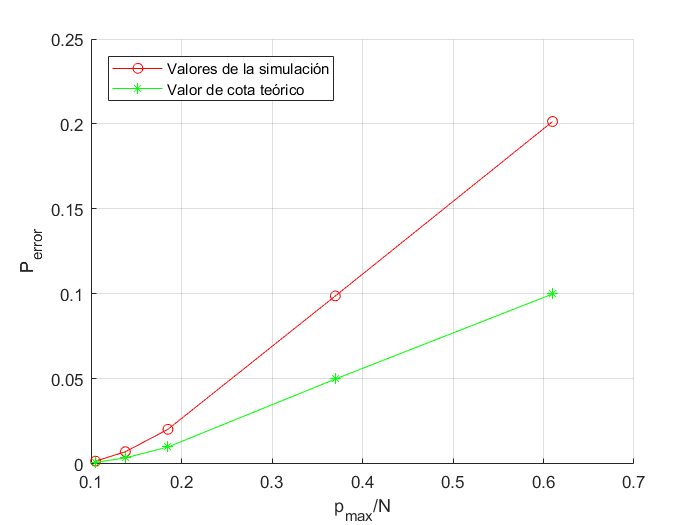

figure(1)
hold on
grid on
plot(double(p_max(1:i))/double(N),P_error(1:i), '-or')
plot(double(p_max)/double(N), P_error_teorico, '-*g')
axis([0.1 0.7 0 0.25])
legend('Valores de la simulación', 'Valor de cota teórico', 'Location', 'northwest')
xlabel('p_{max}/N')
ylabel('P_{error}')

En esta parte busco la máxima cantidad de patrones que puede aprender para cada error.

if ~exist('capacidad', 'var') || i==1
    capacidad = []; % Variable con la que voy a iterar el vector p_max.
end
 %Vector donde voy a guardar las capacidades maximas para cada errro
capacidadActual = p_max(i);
ProbErrores=1;
while ProbErrores>=P_error_teorico(i) && capacidadActual>=0 % Mientras la ProbError sea mayor o igual a la teorica
    % voy bajando la cant de patrones para obtener la capacidad
    patrones = rand([N,capacidadActual]); % Creo la matriz de N x p_max que va a tener p_max patrones.
    patrones = patrones <0.5; % Convierto a 1s y 0s.
    patrones = patrones*2-1; % Convierto a 1s y -1s.
    w = patrones*patrones'; % Creo la matriz de pesos
    w = w/N; %y divido por la cantidad de patrones.
    w = w.*(ones(N)-eye(N)); % Anulo la diagonal
    salida = w*patrones; % Calculo la salida con todos los patrones
    salida=negSign(salida); % Convierto a -1s y 1s
    ProbErrores = sum(sum(abs(salida-patrones))); % Sumo los errores
    ProbErrores= ProbErrores/double(capacidadActual*N); % Calculo la probabilidad
    capacidadActual=capacidadActual-1; % Al final bajo la capacidad actual
end
capacidad = [capacidad capacidadActual];

Una vez que terminé muestro los valores obtenidos contra los teoricos

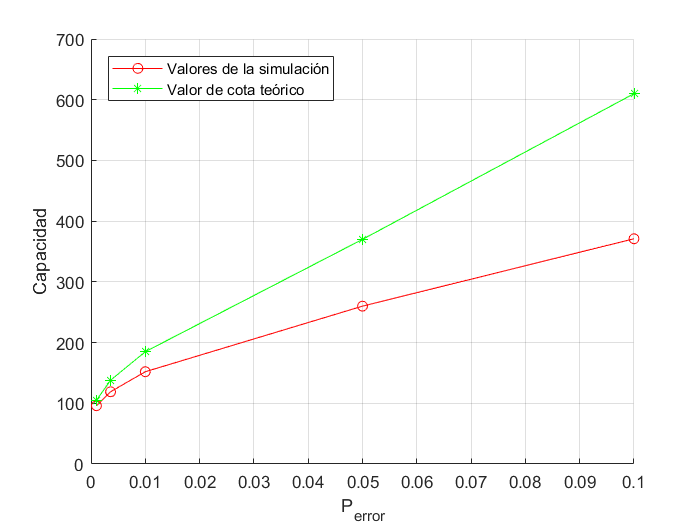

figure(2)
hold on
grid on
plot(P_error_teorico(1:i),double(capacidad), '-or')
plot(P_error_teorico, p_max,'-*g')
legend('Valores de la simulación', 'Valor de cota teórico', 'Location', 'northwest')
xlabel('P_{error}')
ylabel('Capacidad')

i=i+1;
if i == 6
    i=1;
end